% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 5;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-06-24/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Growth(495)_10000_5_2024-06-24-14.46.30.747.csv";
file_path = data_path+file_name;
growth_495 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(395)_10000_5_2024-06-24-14.48.11.540.csv";
file_path = data_path+file_name;
growth_395 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(295)_10000_5_2024-06-24-14.49.50.427.csv";
file_path = data_path+file_name;
growth_295 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(195)_10000_5_2024-06-24-14.51.30.827.csv";
file_path = data_path+file_name;
growth_195 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(95)_10000_5_2024-06-24-14.53.05.150.csv";
file_path = data_path+file_name;
growth_95 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(195_2)_10000_5_2024-06-24-14.54.41.333.csv";
file_path = data_path+file_name;
growth_195_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(295_2)_10000_5_2024-06-24-14.56.09.283.csv";
file_path = data_path+file_name;
growth_295_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(395_2)_10000_5_2024-06-24-14.57.55.733.csv";
file_path = data_path+file_name;
growth_395_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(495_2)_10000_5_2024-06-24-14.59.37.997.csv";
file_path = data_path+file_name;
growth_495_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth(25)_20000_5_2024-06-24-14.24.22.023.csv";
file_path = data_path+file_name;
growth_25 = csvread(file_path, numMetadataRows, 0);



% Configuring and plotting unprocessed data

wavenumber = growth_495(1,:);

% trimming standard sample data to these WN's
t1 = 350;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
growth_495(:, growth_495(1, :) <= t1) = [];
growth_495(:, growth_495(1, :) >= t2) = [];
growth_395(:, growth_395(1, :) <= t1) = [];
growth_395(:, growth_395(1, :) >= t2) = [];
growth_295(:, growth_295(1, :) <= t1) = [];
growth_295(:, growth_295(1, :) >= t2) = [];
growth_195(:, growth_195(1, :) <= t1) = [];
growth_195(:, growth_195(1, :) >= t2) = [];
growth_95(:, growth_95(1, :) <= t1) = [];
growth_95(:, growth_95(1, :) >= t2) = [];
growth_195_2(:, growth_195_2(1, :) <= t1) = [];
growth_195_2(:, growth_195_2(1, :) >= t2) = [];
growth_295_2(:, growth_295_2(1, :) <= t1) = [];
growth_295_2(:, growth_295_2(1, :) >= t2) = [];
growth_395_2(:, growth_395_2(1, :) <= t1) = [];
growth_395_2(:, growth_395_2(1, :) >= t2) = [];
growth_495_2(:, growth_495_2(1, :) <= t1) = [];
growth_495_2(:, growth_495_2(1, :) >= t2) = [];
growth_25(:, growth_25(1, :) <= t1) = [];
growth_25(:, growth_25(1, :) >= t2) = [];

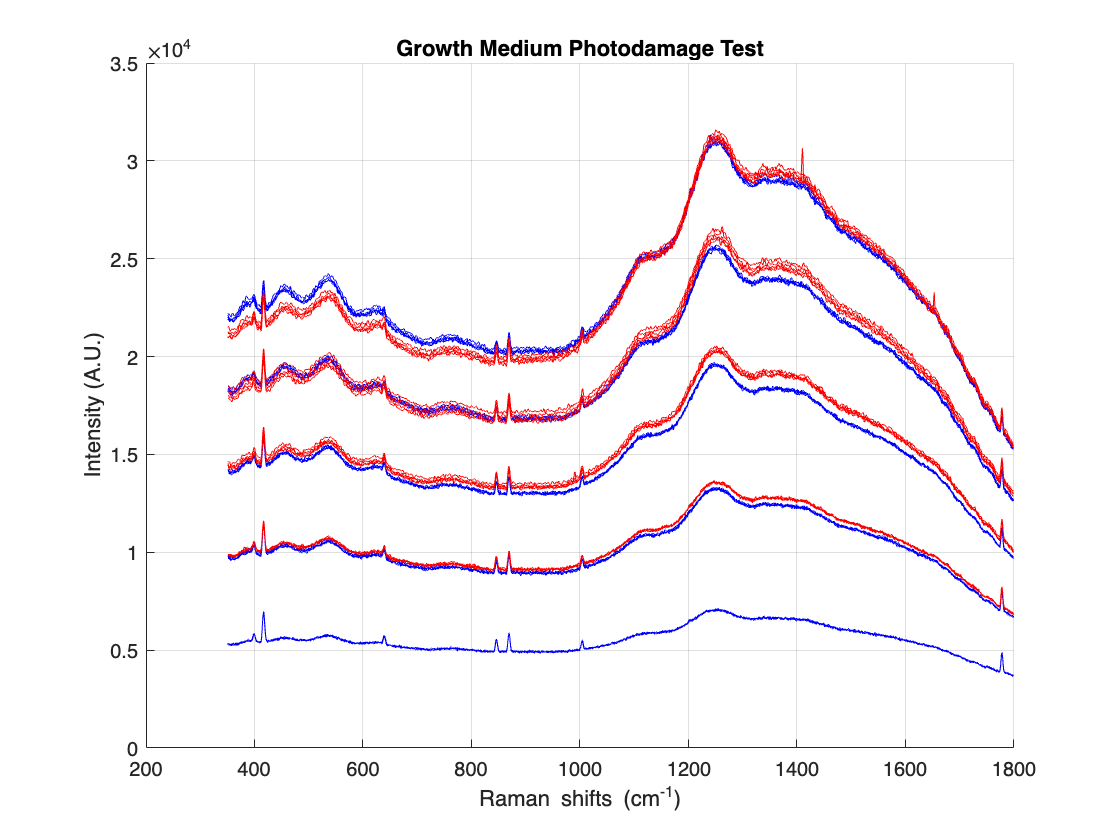

% Plotting

figure;
hold on;
grid on;
plot(wavenumber, growth_495(2:end, :), '-b');
plot(wavenumber, growth_395(2:end, :), '-b');
plot(wavenumber, growth_295(2:end, :), '-b');
plot(wavenumber, growth_195(2:end, :), '-b');
plot(wavenumber, growth_95(2:end, :), '-b');
plot(wavenumber, growth_195_2(2:end, :), '-r');
plot(wavenumber, growth_295_2(2:end, :), '-r');
plot(wavenumber, growth_395_2(2:end, :), '-r');
plot(wavenumber, growth_495_2(2:end, :), '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Photodamage Test');
hold off;

% Pre-processing data

pro_grow495 = apply(growth_495, [6,1,8,2,5,6,7]);
pro_grow395 = apply(growth_395, [6,1,8,2,5,6,7]);
pro_grow295 = apply(growth_295, [6,1,8,2,5,6,7]);
pro_grow195 = apply(growth_195, [6,1,8,2,5,6,7]);
pro_grow95 = apply(growth_95, [6,1,8,2,5,6,7]);
pro_grow25 = apply(growth_25, [6,1,8,2,5,6,7]);
pro_grow195_2 = apply(growth_195_2, [6,1,8,2,5,6,7]);
pro_grow295_2 = apply(growth_295_2, [6,1,8,2,5,6,7]);
pro_grow395_2 = apply(growth_395_2, [6,1,8,2,5,6,7]);
pro_grow495_2 = apply(growth_495_2, [6,1,8,2,5,6,7]);

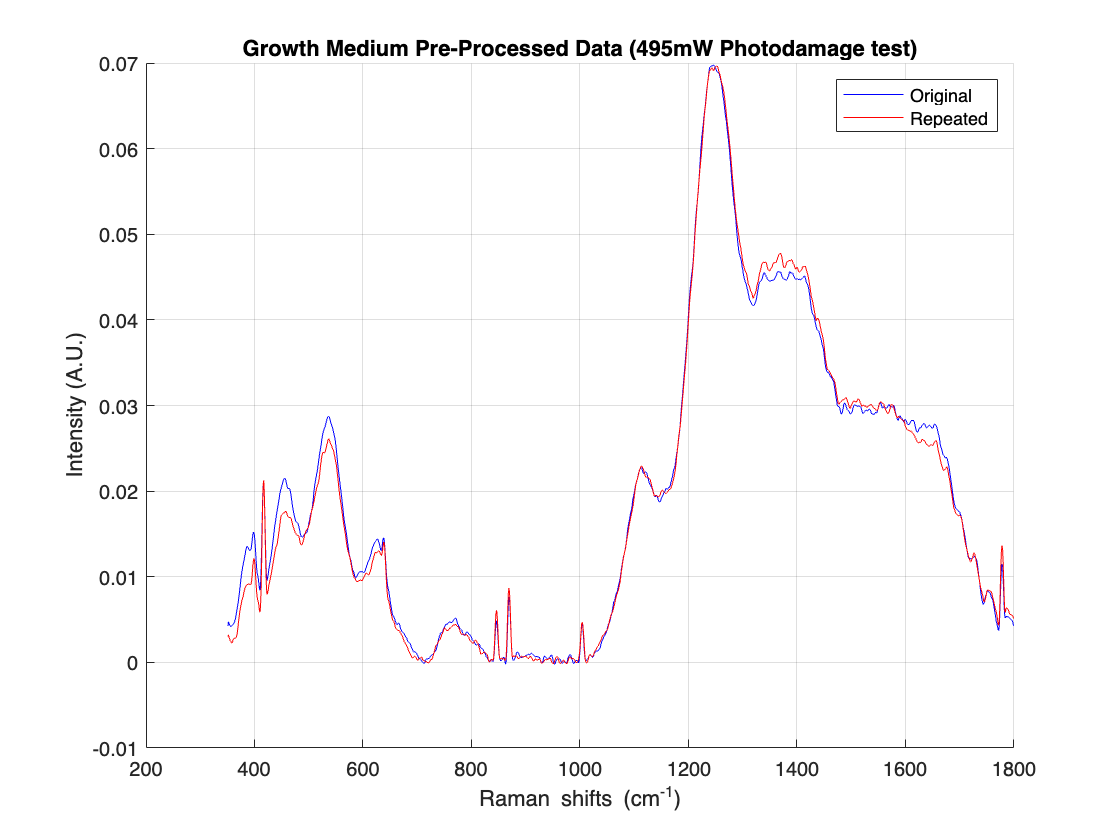

% Plotting results of photodamage test

figure;
hold on;
grid on;
plot(wavenumber, pro_grow495, '-b');
plot(wavenumber, pro_grow495_2, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (495mW Photodamage test)');
legend('Original','Repeated');
hold off;

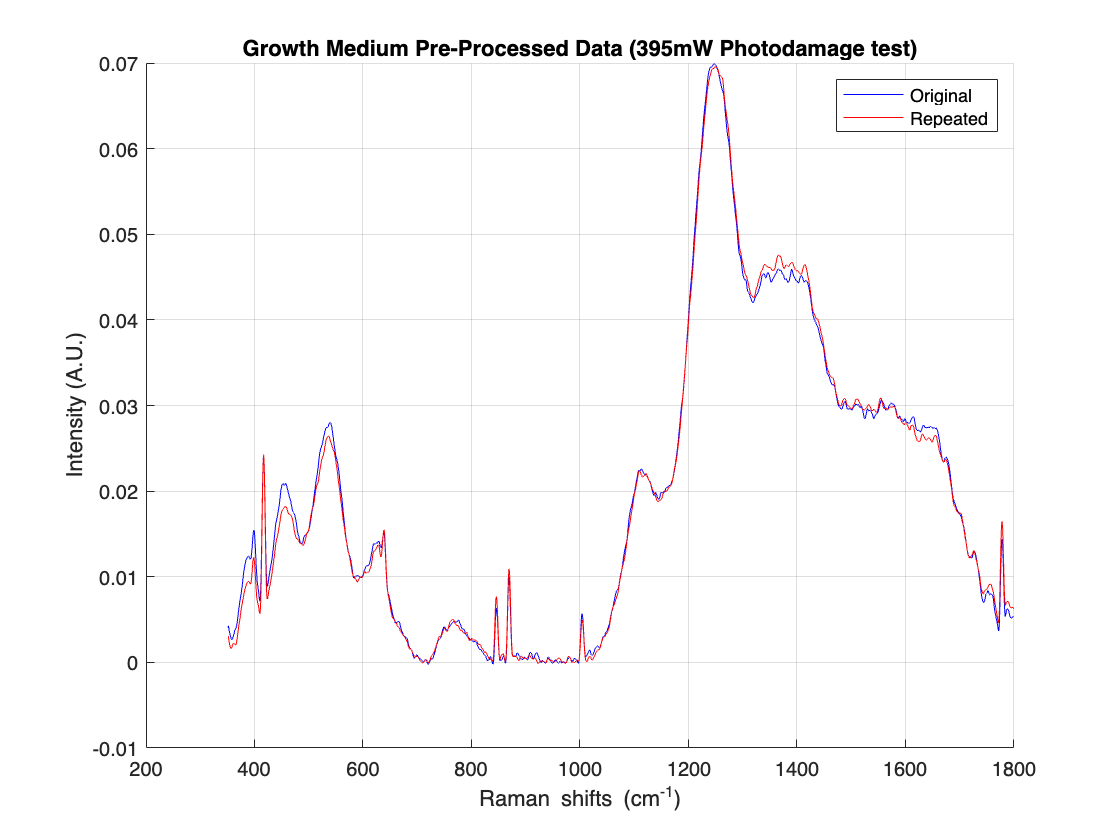

figure;
hold on;
grid on;
plot(wavenumber, pro_grow395, '-b');
plot(wavenumber, pro_grow395_2, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (395mW Photodamage test)');
legend('Original','Repeated');
hold off;

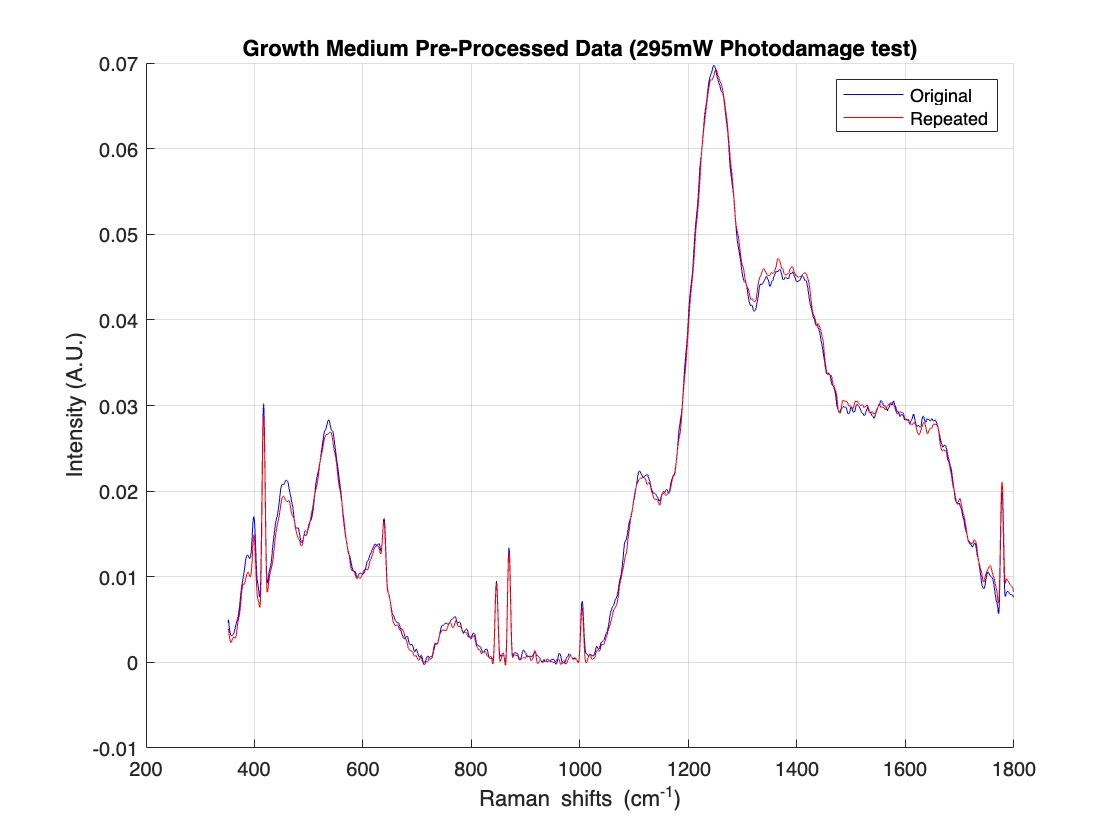

figure;
hold on;
grid on;
plot(wavenumber, pro_grow295, '-b');
plot(wavenumber, pro_grow295_2, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (295mW Photodamage test)');
legend('Original','Repeated');
hold off;

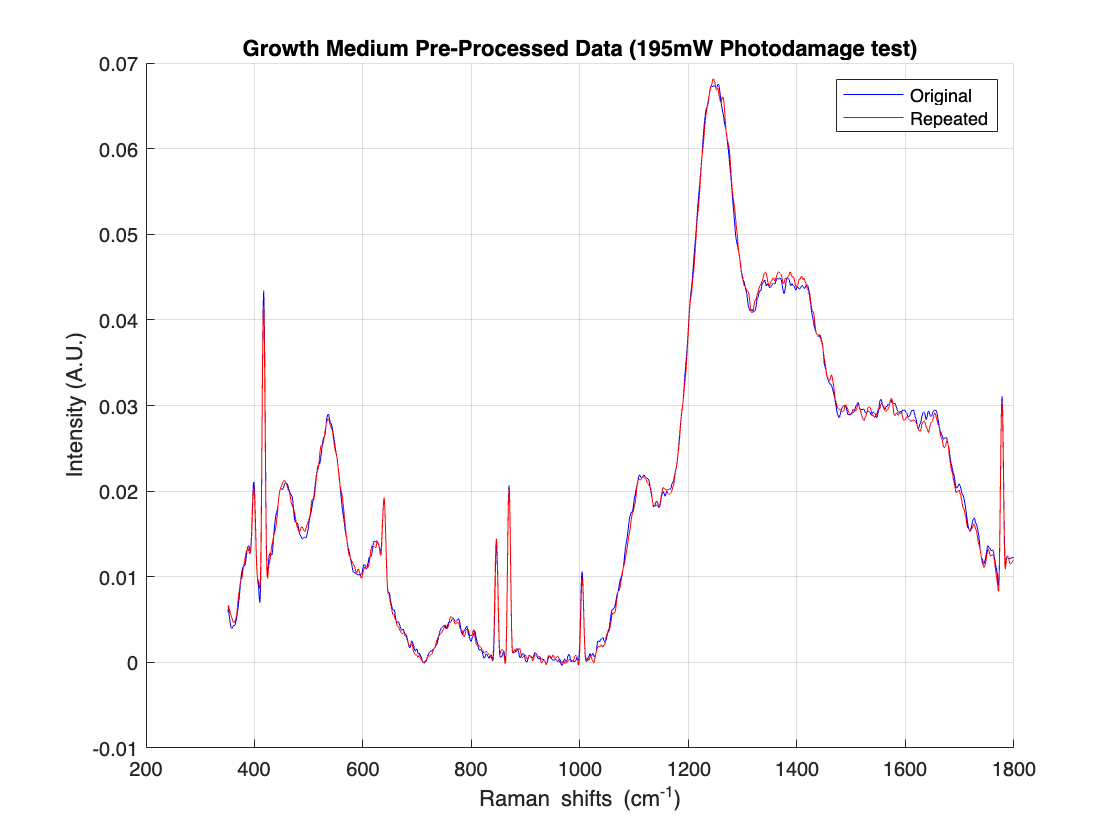

figure;
hold on;
grid on;
plot(wavenumber, pro_grow195, '-b');
plot(wavenumber, pro_grow195_2, '-r');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data (195mW Photodamage test)');
legend('Original','Repeated');
hold off;

a = var([pro_grow495_2; pro_grow495]);
mean(a)

ans =      7.772339653543399e-07


b = var([pro_grow395_2; pro_grow395]);
mean(b)

ans =      4.457536543633455e-07


c = var([pro_grow295_2; pro_grow295]);
mean(c)

ans =      2.907577461484825e-07


d = var([pro_grow195_2; pro_grow195]);
mean(d)

ans =      1.925385757928532e-07


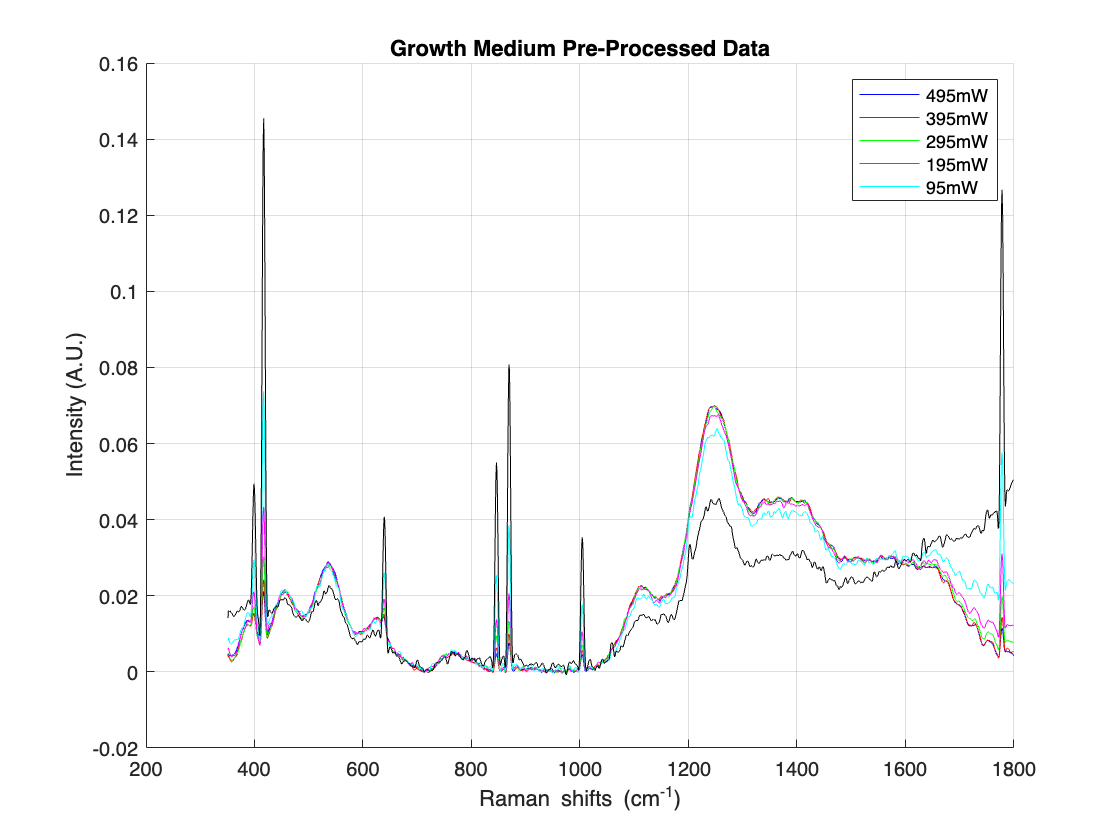

% SNR results

figure;
hold on;
grid on;
plot(wavenumber, pro_grow495, '-b');
plot(wavenumber, pro_grow395, '-r');
plot(wavenumber, pro_grow295, '-g');
plot(wavenumber, pro_grow195, '-m');
plot(wavenumber, pro_grow95, '-c');
plot(wavenumber, pro_grow25, '-k');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data');
legend('495mW','395mW','295mW','195mW','95mW');
hold off;

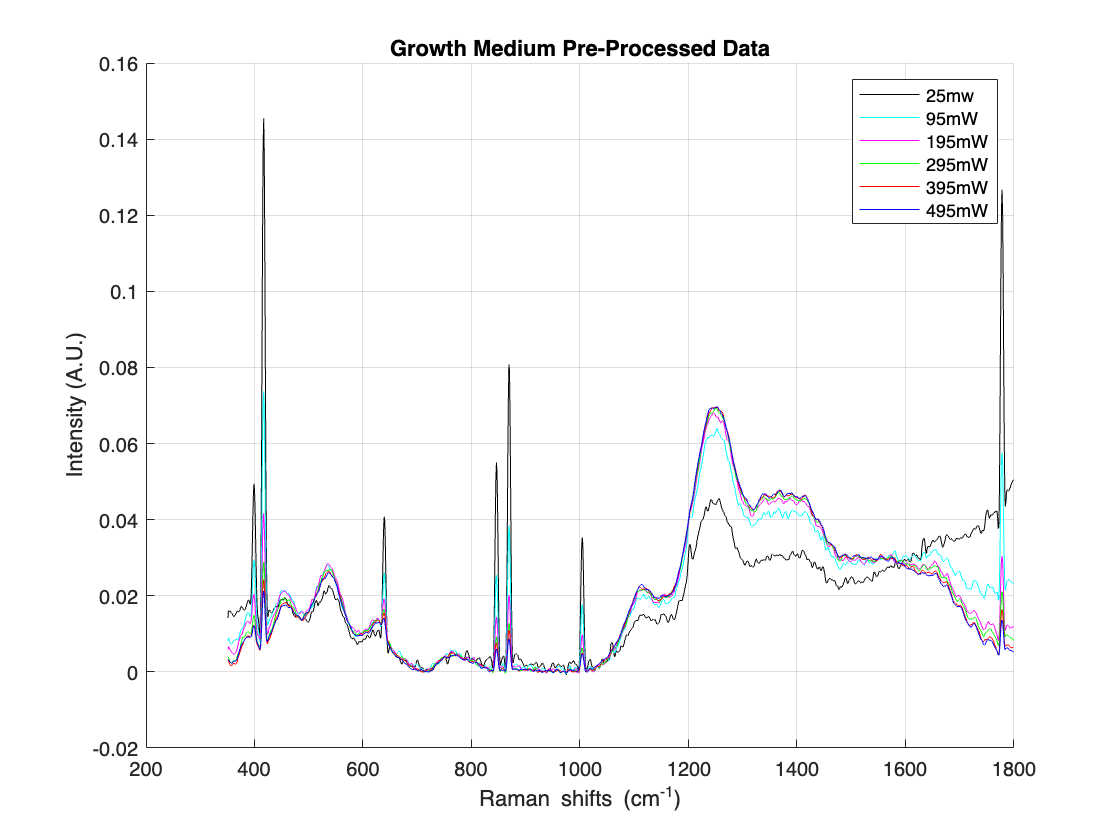

figure;
hold on;
grid on;
plot(wavenumber, pro_grow25, '-k');
plot(wavenumber, pro_grow95, '-c');
plot(wavenumber, pro_grow195_2, '-m');
plot(wavenumber, pro_grow295_2, '-g');
plot(wavenumber, pro_grow395_2, '-r');
plot(wavenumber, pro_grow495_2, '-b');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Pre-Processed Data');
legend('25mw','95mW','195mW','295mW','395mW','495mW');
hold off;

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end

